clear; clc;

%Student ID 2024161152
A1 = 2;
A2 = 5;
L1 = 20 + A1 / 0.5; % Length of the first medium in meters
L2 = 15 + A2 / 0.5; % Length of the second medium in meters
c1 = 1500.0 + 10.0 * A1 - A2; % Speed of sound in the first medium in m/s
c2 = (1800.0 + 20.0 * A2 * A1) * (1 + 0.02 * 1i * (2 + sqrt(A1))); % Speed of sound in the second medium in m/s
rho = 1000; % Density in kg/m^3
f = 500.0 + A2 * 20.0 + A1 % Excitation frequency in Hz

f = 602

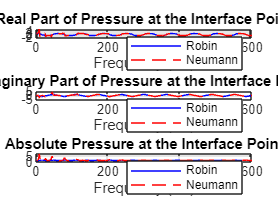

f = 1:2:f;

% Total length and number of points
L = L1 + L2;
ne = 491;

% Mesh
dx = L / ne;
x = 0:dx:L;
n_l = 1:ne;
n_r = 2:ne + 1;

% Preallocate arrays for results
P_interface_robin = zeros(numel(f), 1);
P_interface_neumann = zeros(numel(f), 1);
P_spl_robin = zeros(ne + 1, numel(f)); % for colormap Robin
P_spl_neumann = zeros(ne + 1, numel(f)); % for colormap Neumann

% Loop over frequencies
for n = 1:numel(f)
    w = 2 * pi * f(n); % Angular frequency

    % Initialize matrices
    K = zeros(ne + 1);
    M = zeros(ne + 1);
    C = zeros(ne + 1);
    
    % Assemble global stiffness, mass, and damping matrices
    for ii = 1:ne
        Le = dx;
        ndof = [n_l(ii) n_r(ii)]; % Degrees of freedom for the element
        
        if x(ii) < L1
            % Fluid M1
            [ke1, me1] = keme(Le, rho, c1);
            K(ndof, ndof) = K(ndof, ndof) + ke1;
            M(ndof, ndof) = M(ndof, ndof) + me1;
        elseif x(ii)==L1
            M(n_l(ii),n_l(ii-1))=Le/(6*c1^2*rho);
            M(n_l(ii),n_l(ii))=Le/(3*rho*(1/c1^2+1/c2^2));
            M(n_l(ii),n_l(ii+1))=Le/(6*c2^2*rho);
            K(n_l(ii),n_l(ii-1))=-1/(rho*Le);
            K(n_l(ii),n_l(ii))=2/(rho*Le);
            K(n_l(ii),n_l(ii+1))=-1/(rho*Le);
        else
            % Fluid M2
            [ke2, me2] = keme(Le, rho, c2);
            K(ndof, ndof) = K(ndof, ndof) + ke2;
            M(ndof, ndof) = M(ndof, ndof) + me2;
        end
    end

    % Robin boundary condition (Z = rho * c2)
    Z_robin = rho * c2;
    C(end, end) = 1 / Z_robin;
    KK_robin = K + 1i * w * C - w^2 * M; % K*P + 1i*w*C - w^2*M*P
    F_robin = zeros(ne + 1, 1);
    %drichlet cnodition ant the leftmost node
    KK_robin(1,:) = 0;
    KK_robin(1,1) = 1;
    F_robin(1) = 1;
    P_robin = (KK_robin \ F_robin);
    P_interface_robin(n) = P_robin(n_l(find(x >= L1, 1))); % Pressure at the interface
    P_spl_robin(:, n) = 20 * log10(abs(P_robin) / 1.0); % Sound Pressure Level for colormap

    % Neumann boundary condition (vn = 0)
    C(end, end) = 0;
    KK_neumann = K + 1i * w * C - w^2 * M; % K*P + 1i*w*C - w^2*M*P
    %drichlet cnodition ant the leftmost node
    F_neumann = zeros(ne + 1, 1);
    KK_neumann(1,:) = 0;
    KK_neumann(1,1) = 1;
    F_neumann(1) = 1;
    P_neumann = (KK_neumann \ F_neumann);
    P_interface_neumann(n) = P_neumann(n_l(find(x >= L1, 1))); % Pressure at the interface
    P_spl_neumann(:, n) = 20 * log10(abs(P_neumann) / 1.0); % Sound Pressure Level for colormap
end

% Plot results at the interface point for both boundary conditions
figure;
subplot(3, 1, 1);
plot(f, real(P_interface_robin), 'b', f, real(P_interface_neumann), 'r--');
xlabel('Frequency (Hz)');
ylabel('Real Pressure (Pa)');
title('Real Part of Pressure at the Interface Point');
legend('Robin', 'Neumann');
grid on;

subplot(3, 1, 2);
plot(f, imag(P_interface_robin), 'b', f, imag(P_interface_neumann), 'r--');
xlabel('Frequency (Hz)');
ylabel('Imaginary Pressure (Pa)');
title('Imaginary Part of Pressure at the Interface Point');
legend('Robin', 'Neumann');
grid on;

subplot(3, 1, 3);
plot(f, abs(P_interface_robin), 'b', f, abs(P_interface_neumann), 'r--');
xlabel('Frequency (Hz)');
ylabel('Absolute Pressure (Pa)');
title('Absolute Pressure at the Interface Point');
legend('Robin', 'Neumann');
grid on;

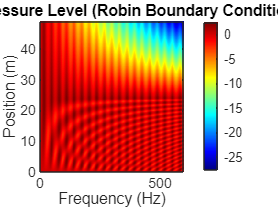


% Create colormap plot for Sound Pressure Level
figure;
imagesc(f, x, P_spl_robin); % Sound Pressure Level for Robin
colorbar;
xlabel('Frequency (Hz)');
ylabel('Position (m)');
title('Sound Pressure Level (Robin Boundary Condition)');
set(gca, 'YDir', 'normal'); % Correct the y-axis direction
colormap(jet);

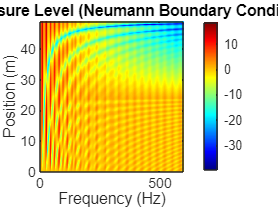


figure;
imagesc(f, x, P_spl_neumann); % Sound Pressure Level for Neumann
colorbar;
xlabel('Frequency (Hz)');
ylabel('Position (m)');
title('Sound Pressure Level (Neumann Boundary Condition)');
set(gca, 'YDir', 'normal'); % Correct the y-axis direction
colormap(jet);